# Behaviour: Scanning Sessions

I analyze here the behaviour of participants in the scanning sessions, across all 5 runs and for each run separately. The purpose of this analysis is to serve as a first-line sanity check and to decide on run or subject exclusion based on our pre-regitered criteria.  

## 0. Load data

clear;
clc;

data_struct = loadData()

data_struct =   Map with properties:

        Count: 73
      KeyType: char
    ValueType: any


subjects = {'01RoYi','02XiHo','03JaVe','04NiSi','05PeYa','06KuSh',...
    '07AnWo','08LiBa', '09KeVa', '10MaIv', '11YaSi', '12JaGu',...
    '13ChSc','14SaMc','15ChFi', '16JoDa', '17IvSi','18LuHe','19ElBo','20MiLa',...
    '21ShZh', '22PeYe','23InMa','24WePi','25AyLe', '26DeCa','27LoLi',...
    '28WiTa', '29CrRa','30OrAl'};
toExclude = zeros(length(subjects),5);


## 1. Trial Misses

The cutoff criterion for trial misses is 20%. The reference line indicates the exclusion criterion.

For participant 12JaGu:


Run 1 was excluded for missing too many discrimination trials 



For participant 25AyLe:


Run 2 was excluded for missing too many discrimination trials 



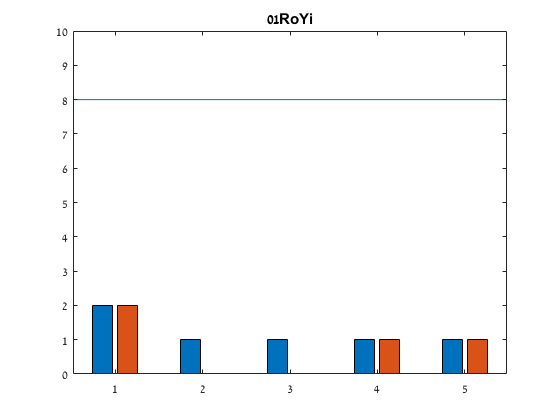

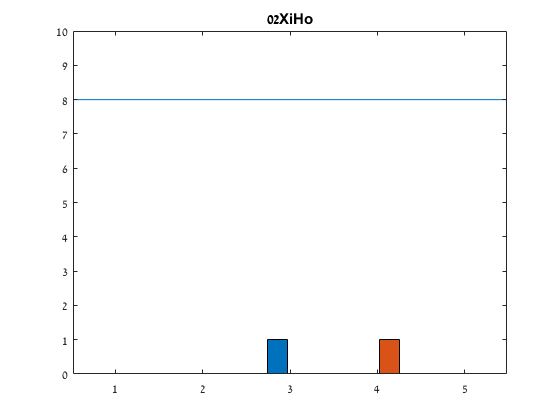

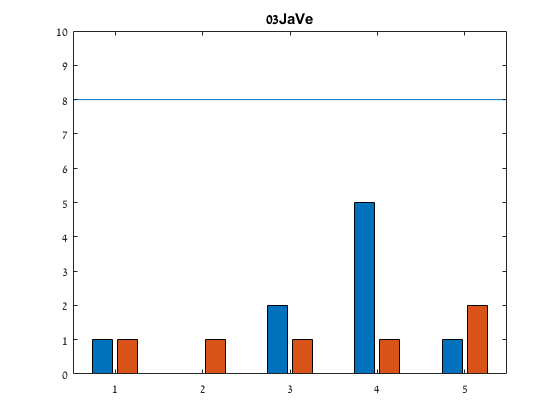

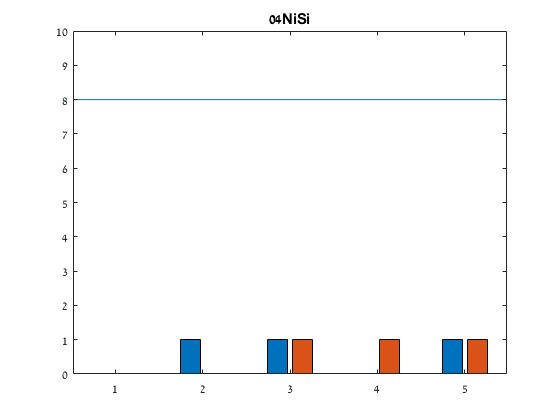

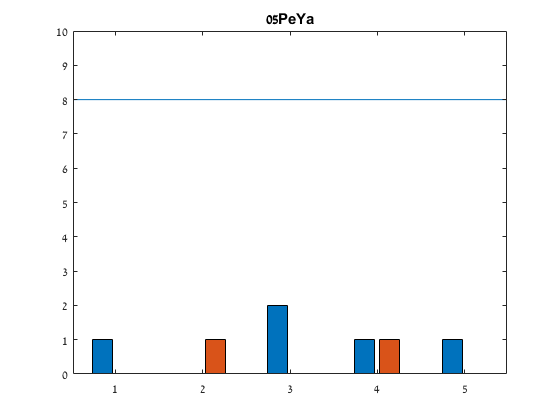

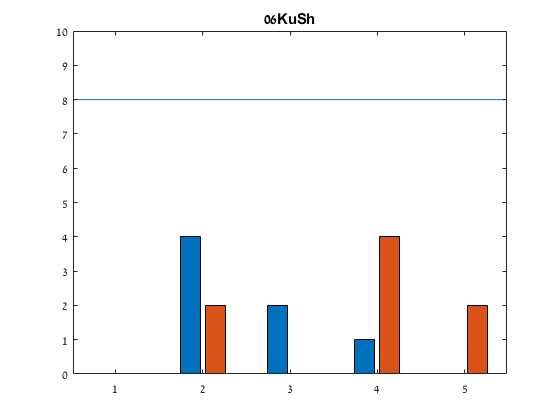

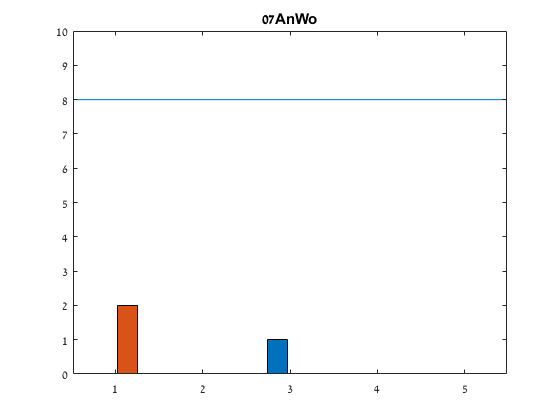

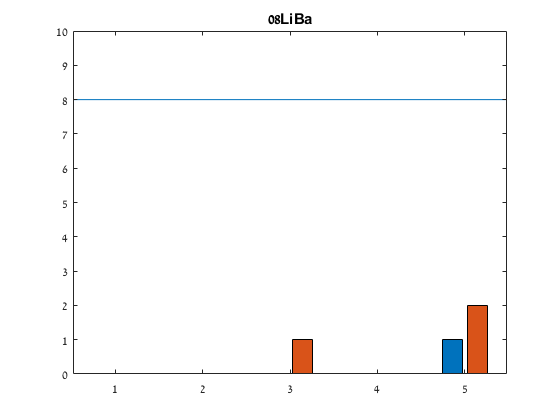

totalMissesExclusions = [0,0];

for s = 1:length(subjects)
    
    DisMisses = [];
    DetMisses = [];
    subject = data_struct(subjects{s});
    figure;
    
    for run_num = 1:length(subject.DisRT)/40
        
        DisNaNCount = sum(isnan(subject.DisRT((run_num-1)*40+1:run_num*40)));
        DetNaNCount = sum(isnan(subject.DetRT((run_num-1)*40+1:run_num*40)));
        
        DisMisses = [DisMisses DisNaNCount];
        DetMisses = [DetMisses DetNaNCount];
        
    end
    
    if any(DisMisses>8)
        
        if mean(DisMisses)>8
            disp(sprintf('Participant %s is excluded for missing too many discrimination trials',subjects{s}))
            disp(repmat('=',1,60))
            toExclude(s,:)=1;
            totalMissesExclusions(1) = totalMissesExclusions(1)+1;
        else
            disp(sprintf('For participant %s:',subjects{s}))
            disp(sprintf('Run %d was excluded for missing too many discrimination trials \n',find(DisMisses>8)))
            disp(repmat('=',1,60))
            toExclude(s, find(DisMisses>8))=1;
            totalMissesExclusions(2) = totalMissesExclusions(2)+1;
        end
    end
    
   if any(DetMisses>8)

       if mean(DetMisses)>8 && any(toExclude(s,:)==0)
            disp(sprintf('Participant %s is excluded for missing too many detection trials',subjects{s}))
            disp(repmat('=',1,60))
            toExclude(s,:)=1;
            totalMissesExclusions(1) = totalMissesExclusions(1)+1;
        elseif toExclude(s,run_num)==0
            disp(sprintf('For participant %s:',subjects{s})) 
            disp(sprintf('Run %d was excluded for missing too many detection trials \n',find(DetMisses>8)))
            disp(repmat('=',1,60))
            toExclude(s,find(DisMisses>8))=1;
            totalMissesExclusions(2) = totalMissesExclusions(2)+1;
        end
    end
    
     bar([DisMisses' DetMisses']);
        
     refline(0,8);
        
     ylim([0,10]); 
        
     title(subjects{s});
end

## 2. Accuracy

Runs in which accuracy in at least one of the tasks was below 60% are excluded from further analysis.

Subjects for which overall accuracy in at least one of the tasks was below 60% are excluded from further analysis.

For participant 03JaVe:


Run 2 was excluded due to low accuracy in the detection task 



For participant 14SaMc:


Run 2 was excluded due to low accuracy in the detection task 



For participant 15ChFi:


Run 3 was excluded due to low accuracy in the detection task 



For participant 19ElBo:


Run 3 was excluded due to low accuracy in the detection task 



For participant 21ShZh:


Run 1 was excluded due to low accuracy in the discrimination task 
Run 2 was excluded due to low accuracy in the discrimination task 
Run 4 was excluded due to low accuracy in the discrimination task 
Run 5 was excluded due to low accuracy in the discrimination task 



For participant 25AyLe:


Run 1 was excluded due to low accuracy in the detection task 



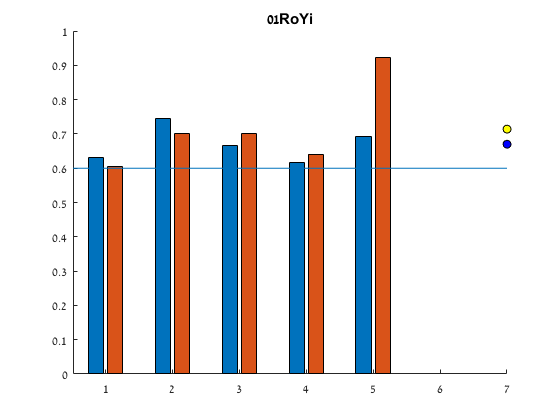

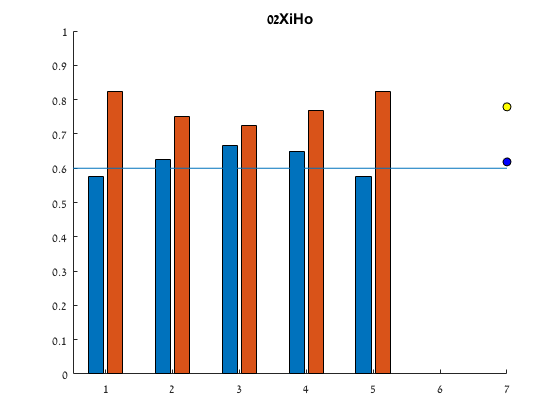

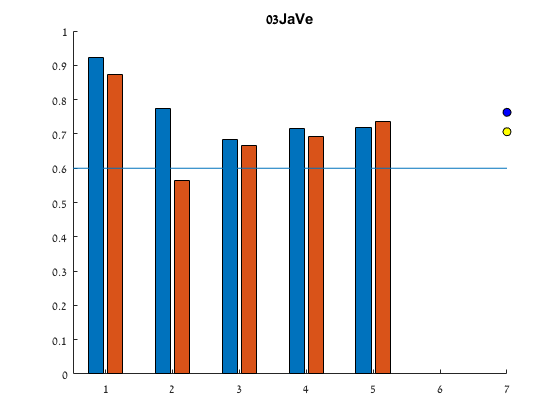

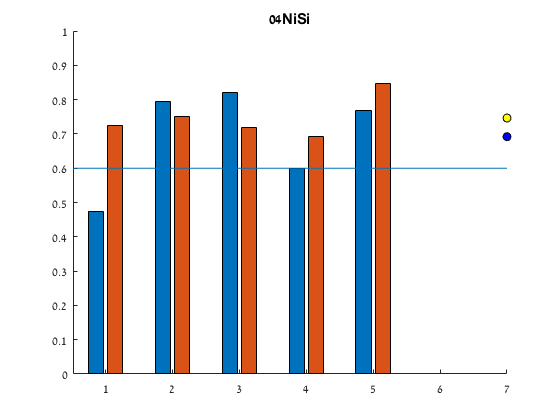

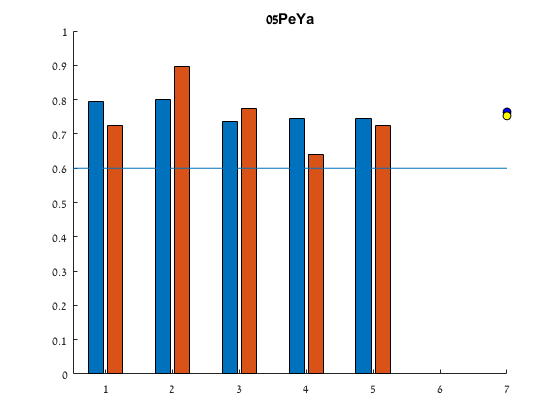

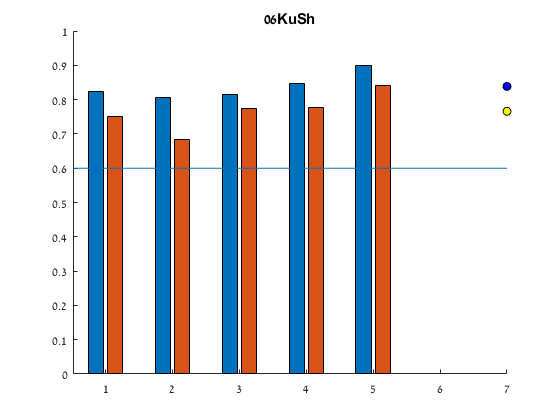

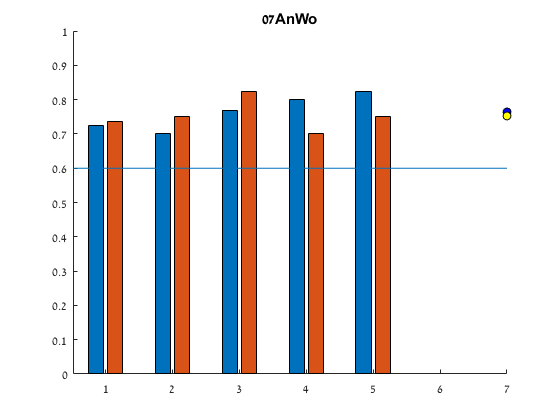

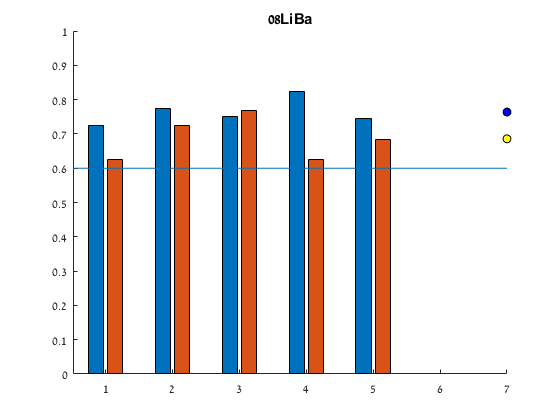

totalAccuracyExclusions = [0,0];

for s = 1:length(subjects)
    
    DisAcc = [];
    DetAcc = [];
    subject = data_struct(subjects{s});
    figure;
    hold on;
    
    for run_num = 1:length(subject.DisRT)/40
        
        DisMeanCorrect = nanmean(subject.DisCorrect((run_num-1)*40+1:run_num*40));
        DetMeanCorrect = nanmean(subject.DetCorrect((run_num-1)*40+1:run_num*40));
        
        DisAcc = [DisAcc DisMeanCorrect];
        DetAcc = [DetAcc DetMeanCorrect];
        
    end
    
    bar([DisAcc' DetAcc']);
          
    %plot mean accuracy as a point
    scatter(length(DisAcc)+2,mean(DisAcc), 'MarkerEdgeColor','black','MarkerFaceColor','blue')
    scatter(length(DetAcc)+2,mean(DetAcc), 'MarkerEdgeColor','black','MarkerFaceColor','yellow')

    refline(0,0.6);
    
    if any(DisAcc<0.6)
        if mean(DisAcc)<0.6 && any(toExclude(s,:)== 0)
                disp(sprintf('Participant %s is excluded due to low accuracy in the discrimination task',subjects{s}))
                disp(repmat('=',1,60))
                toExclude(s,:)=1;
                totalAccuracyExclusions(1) = totalAccuracyExclusions(1)+1;                
        elseif toExclude(s,run_num)==1
                disp(sprintf('For participant %s:',subjects{s}))
                disp(sprintf('Run %d was excluded due to low accuracy in the discrimination task \n',find(DisAcc<0.6)))
                disp(repmat('=',1,60))
                toExclude(s,find(DisAcc<0.6))=1;
                totalAccuracyExclusions(2) = totalAccuracyExclusions(2)+1;
        end
    end
        
    if any(DetAcc<0.6)
        if mean(DetAcc)<0.6 && any(toExclude(s,:)== 0)
            disp(sprintf('Participant .%s is excluded due to low accuracy in the detection task \n \n',subjects{s}))
            disp(repmat('=',1,60))
            toExclude(s,:)=1;
        elseif toExclude(s,run_num)==0
            disp(sprintf('For participant %s:',subjects{s}))
            disp(sprintf('Run %d was excluded due to low accuracy in the detection task \n',find(DetAcc<0.6)))
            disp(repmat('=',1,60))
            toExclude(s,find(DetAcc<0.6))=1;
            totalAccuracyExclusions(2) = totalAccuracyExclusions(2)+1;
        end
    end
        
    ylim([0,1]);
    title(subjects{s});
end

## 3. Response Bias

Runs in which participants had a heavy response bias (>0.8) in one or more of the tasks are excluded.

Participants with a heavy overall response bias (>0.75) are excluded.

Participant 02XiHo is excluded due to a heavy response bias in the discrimination task


For participant 09KeVa:


Run 1 was excluded due to a heavy response bias in the detection task 



For participant 10MaIv:


Run 2 was excluded due to a heavy response bias in the discrimination task 
Run 4 was excluded due to a heavy response bias in the discrimination task 



For participant 22PeYe:


Run 3 was excluded due to a heavy response bias in the detection task 



For participant 25AyLe:


Run 1 was excluded due to a heavy response bias in the detection task 
Run 4 was excluded due to a heavy response bias in the detection task 



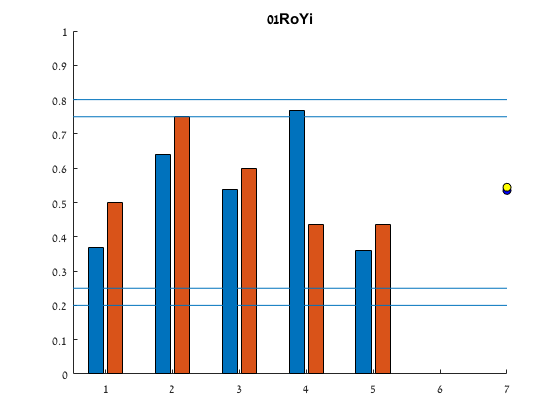

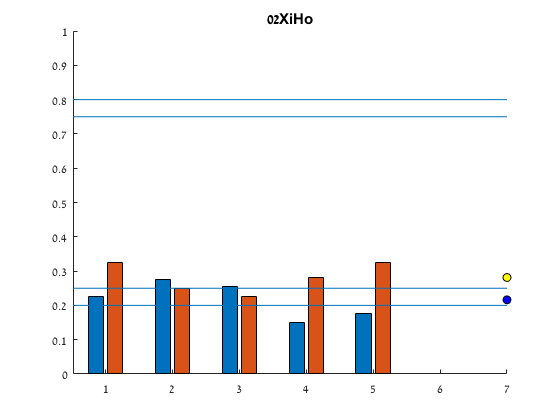

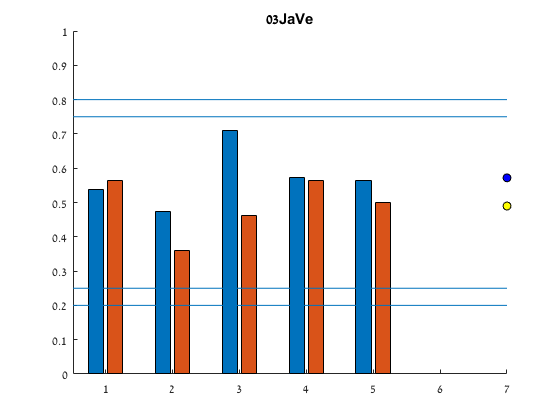

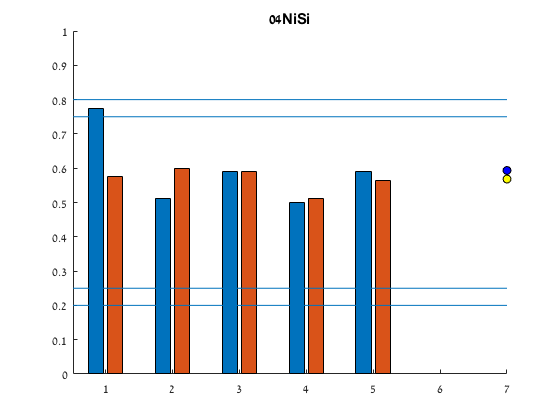

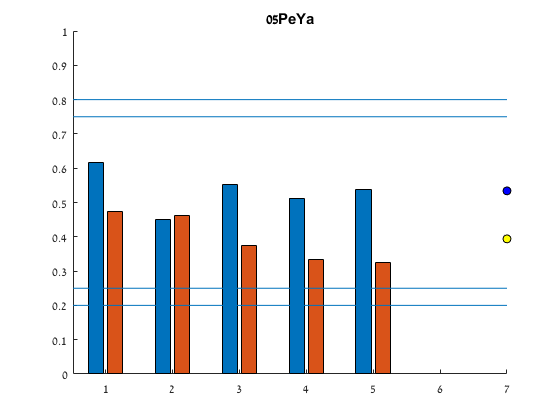

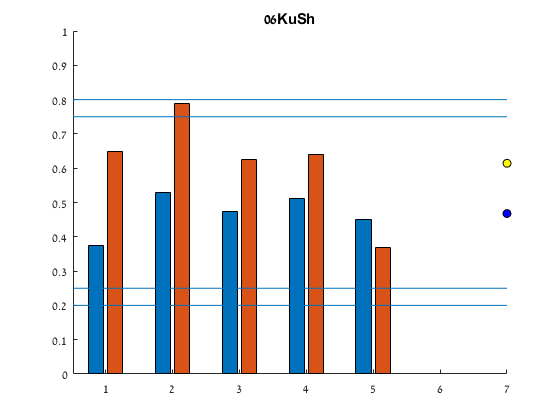

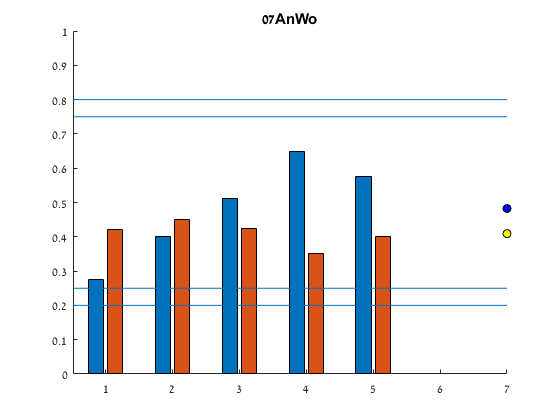

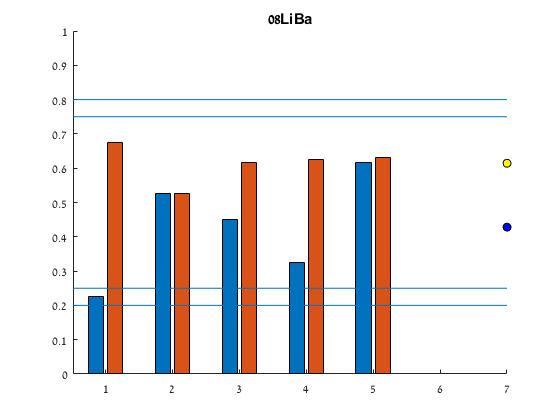

totalBiasExclusions = [0,0];

for s = 1:length(subjects)
    
    DisBias = [];
    DetBias = [];
    subject = data_struct(subjects{s});
    figure;
    hold on;
    
    for run_num = 1:length(subject.DisRT)/40
        
        DisMeanResp = nanmean(subject.DisResp((run_num-1)*40+1:run_num*40));
        DetMeanResp = nanmean(subject.DetResp((run_num-1)*40+1:run_num*40));
        
        DisBias = [DisBias DisMeanResp];
        DetBias = [DetBias DetMeanResp];
        
    end
    
    bar([DisBias' DetBias']);
          
    %plot mean response bias as a point
    scatter(length(DisBias)+2,mean(DisBias), 'MarkerEdgeColor','black','MarkerFaceColor','blue')
    scatter(length(DetBias)+2,mean(DetBias), 'MarkerEdgeColor','black','MarkerFaceColor','yellow')

    refline(0,0.75); %the external lines are subject-wise criteria
    refline(0,0.25);
    refline(0,0.8); %the internal lines are run-wise criteria
    refline(0,0.2);

    
    if abs(mean(DisBias)-0.5)>0.25 && any(toExclude(s,:)==0)
            disp(sprintf('Participant %s is excluded due to a heavy response bias in the discrimination task',subjects{s}))
            disp(repmat('=',1,60))
            toExclude(s,:)=1;
            totalBiasExclusions(1) = totalBiasExclusions(1)+1;
    elseif any(abs(DisBias-0.5)>0.3 & toExclude(s,:)==0) 
            disp(sprintf('For participant %s:',subjects{s}))
            disp(sprintf('Run %d was excluded due to a heavy response bias in the discrimination task \n',find(abs(DisBias-0.5)>0.3)))
            disp(repmat('=',1,60))
            toExclude(s,find(abs(DisBias-0.5)>0.3))=1;
            totalBiasExclusions(2) = totalBiasExclusions(2)+1;
    end
        
    if abs(mean(DetBias)-0.5)>0.25 && any(toExclude(s,:)==0)
            disp(sprintf('Participant %s is excluded due to a heavy response bias in the detection task',subjects{s}))
            disp(repmat('=',1,60))
            toExclude(s,:)=1;
            totalBiasExclusions(1) = totalBiasExclusions(1)+1;
    elseif any(abs(DetBias-0.5)>0.3 & toExclude(s,:)==0)
            disp(sprintf('For participant %s:',subjects{s}))
            disp(sprintf('Run %d was excluded due to a heavy response bias in the detection task \n',find(abs(DetBias-0.5)>0.3)))
            disp(repmat('=',1,60))
            toExclude(s,find(abs(DetBias-0.5)>0.3))=1;
            totalBiasExclusions(2) = totalBiasExclusions(2)+1;
    end
   
    ylim([0,1]);
    title(subjects{s});
end

## 4. Confidence

For confidence related analyses, we exclude runs in which a particular answer was accompanied by the same confidence rating in 95% of the trials.

I couldn't think of a good way to represent confidence ratings, so I went with a stacked bar plot. 

Run 3 of participant 11YaSi was excluded from confidence analysis 



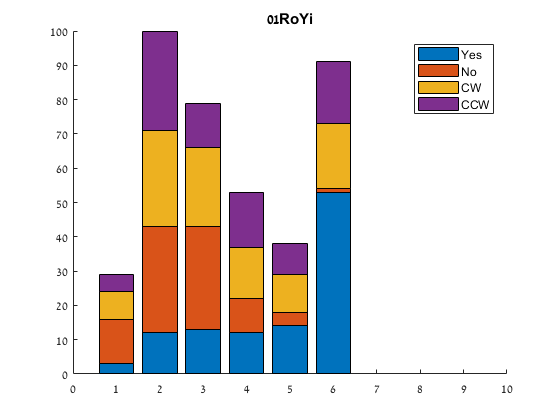

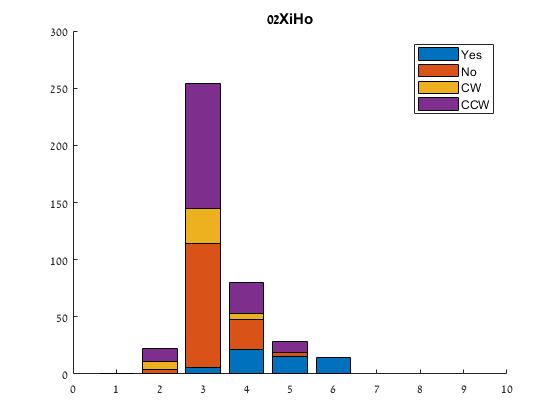

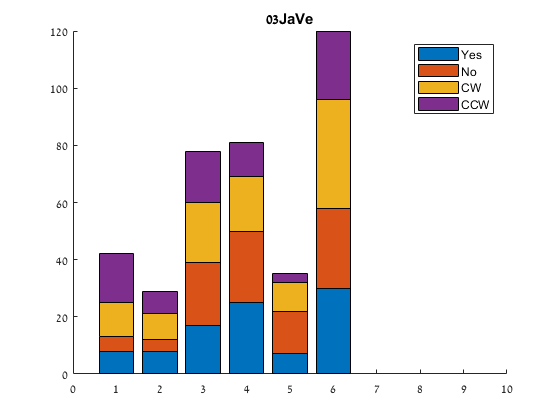

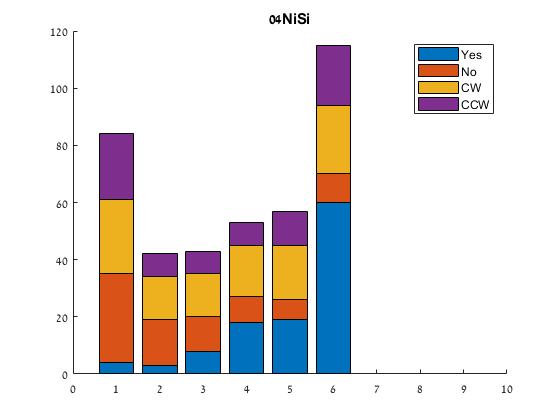

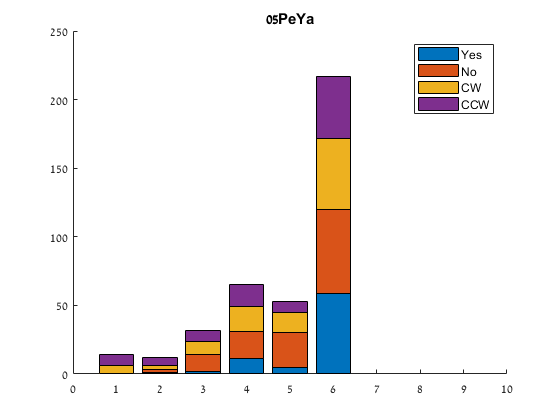

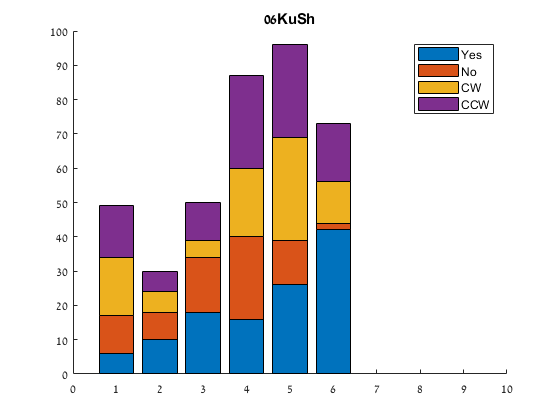

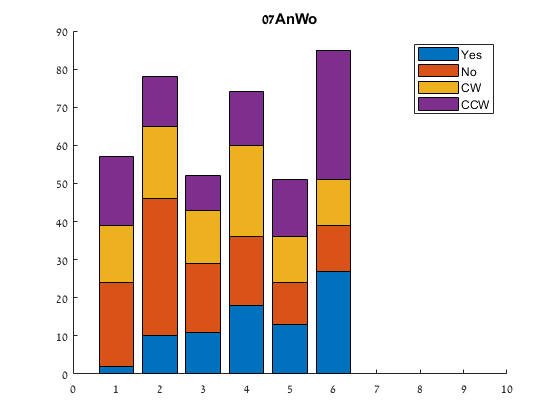

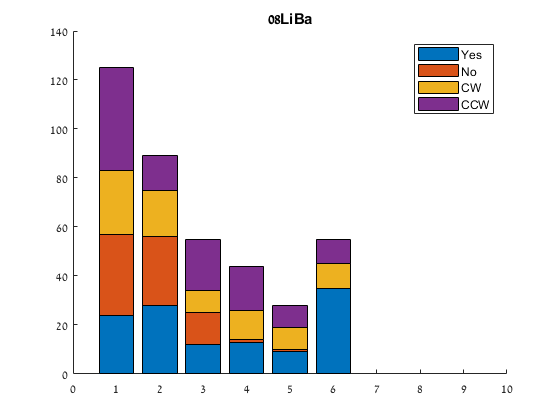

totalConfidenceExclusions = [0,0];    

for s = 1:length(subjects)
    
   
    subject = data_struct(subjects{s});

    
    for run_num = 1:length(subject.DisRT)/40
        
%         figure;
%         title(sprintf('%s: run number %d', subjects{s}, run_num))
%         hold on;
        range = (run_num-1)*40+1:run_num*40;
        conf_matrix = [hist(subject.DetConf(subject.DetResp(range)==1),1:6);... %yes responses
                        hist(subject.DetConf(subject.DetResp(range)==0),1:6);... %no responses
                        hist(subject.DisConf(subject.DisResp(range)==1),1:6);... %CW responses
                        hist(subject.DisConf(subject.DisResp(range)==0),1:6)];    %CCW responses
                    
%         bar(conf_matrix','stacked');
%         xlim([0,10]);
%         legend('Yes','No','CW','CCW')
        
        %check if confidence ratings meet the exclusion criterion
        normalized_conf_matrix = conf_matrix./(repmat(sum(conf_matrix,2),1,6));
        if any(normalized_conf_matrix(:)>0.95) && toExclude(s,run_num)==0
            toExclude(s,run_num)=0.5;
            disp(sprintf('Run %d of participant %s was excluded from confidence analysis \n',run_num, subjects{s}))
            disp(repmat('=',1,60))
            totalConfidenceExclusions(2) = totalConfidenceExclusions(2)+1;
        end
    end
  
    %plot global confidence distribution
    conf_matrix = [hist(subject.DetConf(subject.DetResp==1),1:6);... %yes responses
                        hist(subject.DetConf(subject.DetResp==0),1:6);... %no responses
                        hist(subject.DisConf(subject.DisResp==1),1:6);... %CW responses
                        hist(subject.DisConf(subject.DisResp==0),1:6)];    %CCW responses
    figure;
    hold on
    title(subjects{s})
    bar(conf_matrix','stacked');
    xlim([0,10]);
    legend('Yes','No','CW','CCW')
    
end

## 5. Response Conditional ROCs

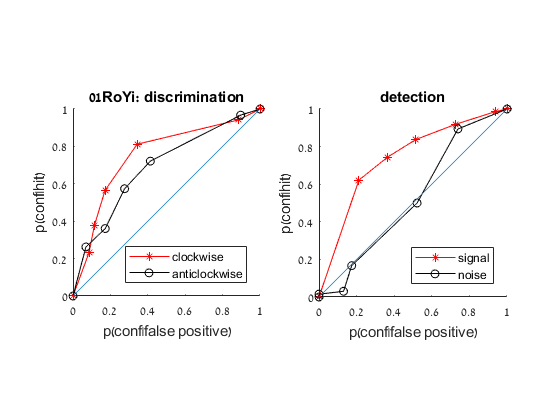

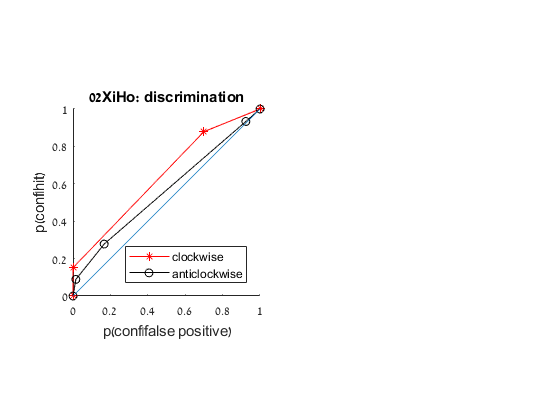

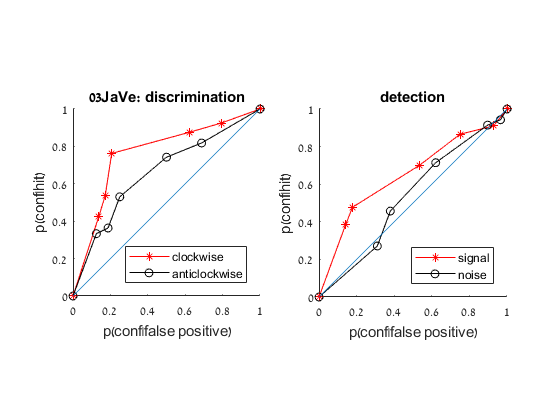

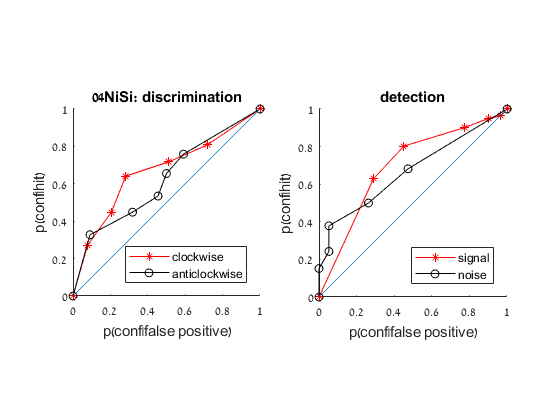

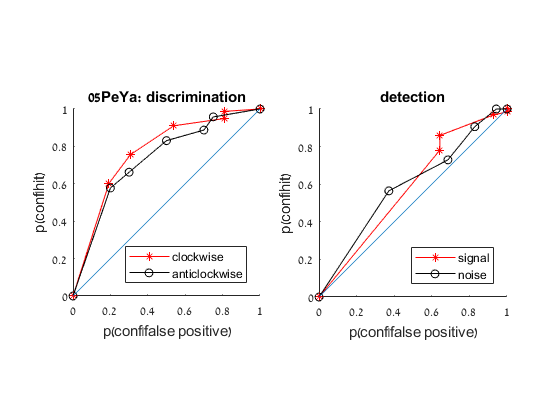

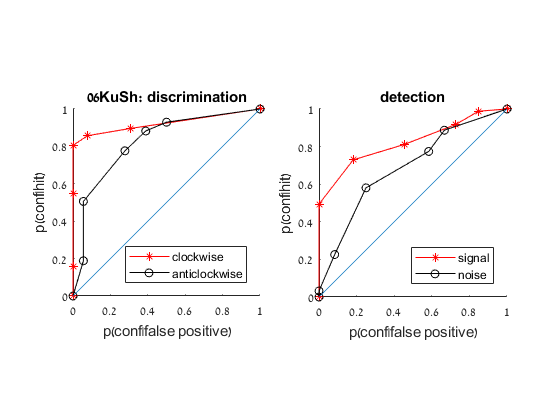

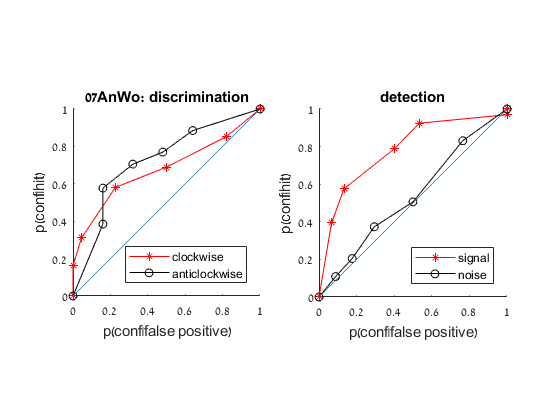

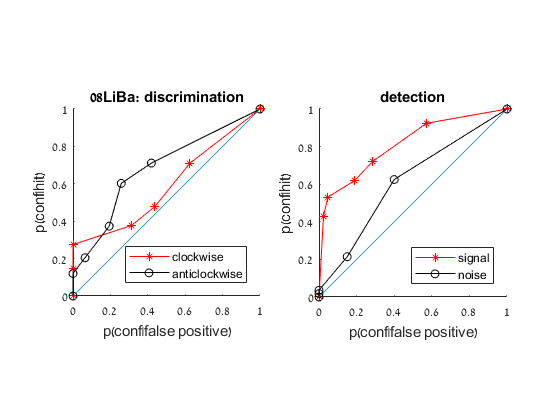

[ACGroup, CCGroup,CAGroup, AAGroup] = deal([]);
[SignalYesGroup, SignalNoGroup, NoiseYesGroup, NoiseNoGroup] = deal([]);

for s=1:length(subjects)
    
    subject = data_struct([subjects{s}]);

    
    %break into taskXresponseXsignal
    DisCC = histc(subject.DisConf(subject.DisSignal==1 & subject.DisResp==1),1:6);
    DisCA = histc(subject.DisConf(subject.DisSignal==1 & subject.DisResp==0),1:6);
    DisAC = histc(subject.DisConf(subject.DisSignal==0 & subject.DisResp==1),1:6);
    DisAA = histc(subject.DisConf(subject.DisSignal==0 & subject.DisResp==0),1:6);
    DetSignalYes = histc(subject.DetConf(subject.DetSignal==1 & subject.DetResp==1),1:6);
    DetSignalNo = histc(subject.DetConf(subject.DetSignal==1 & subject.DetResp==0),1:6);
    DetNoiseYes = histc(subject.DetConf(subject.DetSignal==0 & subject.DetResp==1),1:6);
    DetNoiseNo = histc(subject.DetConf(subject.DetSignal==0 & subject.DetResp==0),1:6);
    

    %% plot discrimination
    figure;
    subplot(1,2,1);
    hold on;
    axis equal
    
    %up responses
    plot([0; cumsum(DisAC(end:-1:1))/sum(DisAC)],...
        [0; cumsum(DisCC(end:-1:1))/sum(DisCC)], '-*r');
    
    ACGroup = [ACGroup [0; cumsum(DisAC(end:-1:1))/sum(DisAC)]];
    CCGroup = [CCGroup [0; cumsum(DisCC(end:-1:1))/sum(DisCC)]];

    %down responses
    plot([0; cumsum(DisCA(end:-1:1))/sum(DisCA)],...
        [0; cumsum(DisAA(end:-1:1))/sum(DisAA)], '-ok');
    
    AAGroup = [AAGroup [0; cumsum(DisAA(end:-1:1))/sum(DisAA)]];
    CAGroup = [CAGroup [0; cumsum(DisCA(end:-1:1))/sum(DisCA)]];
    
    xlabel('p(conf|false positive)');
    ylabel('p(conf|hit)');
    title([subjects{s}, ': discrimination']);
    xticks(0:0.2:1); xlim([0,1]);
    yticks(0:0.2:1); ylim([0,1]);
    refline(1,0);
    legend('clockwise', 'anticlockwise', 'Location', 'southeast')
    
    %% plot detection
    if sum(subject.DetSignal==0 & subject.DetResp==1)>1
        subplot(1,2,2);
        hold on;
        axis equal
        
        %yes responses
        plot([0; cumsum(DetNoiseYes(end:-1:1))/sum(DetNoiseYes)],...
            [0; cumsum(DetSignalYes(end:-1:1))/sum(DetSignalYes)], '-*r');
        
        NoiseYesGroup = [NoiseYesGroup [0; cumsum(DetNoiseYes(end:-1:1))/sum(DetNoiseYes)]];
        SignalYesGroup = [SignalYesGroup [0; cumsum(DetSignalYes(end:-1:1))/sum(DetSignalYes)]];
        
        %no responses
        plot([0; cumsum(DetSignalNo(end:-1:1))/sum(DetSignalNo)],...
            [0; cumsum(DetNoiseNo(end:-1:1))/sum(DetNoiseNo)],'-ok');
    
        NoiseNoGroup = [NoiseNoGroup [0; cumsum(DetNoiseNo(end:-1:1))/sum(DetNoiseNo)]];
        SignalNoGroup = [SignalNoGroup [0;
            cumsum(DetSignalNo(end:-1:1))/sum(DetSignalNo)]];
        
        xlabel('p(conf|false positive)');
        ylabel('p(conf|hit)');
        title('detection');
        xticks(0:0.2:1); xlim([0,1]);
        yticks(0:0.2:1); ylim([0,1]);
        refline(1,0);
        legend('signal', 'noise', 'Location', 'southeast')
    end
end

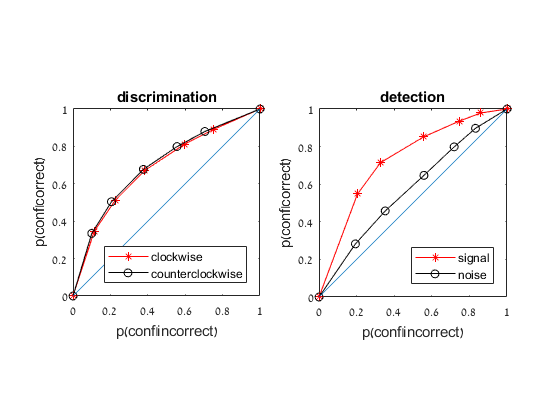

figure;

%discrimination
subplot(1,2,1);
%up responses
% errorbarxy(mean(DownUpGroup,2),mean(UpUpGroup,2), std(DownUpGroup')', std(UpUpGroup')',[],[],'-*r','b');
plot(mean(ACGroup,2),mean(CCGroup,2), '-*r');

hold on;
axis equal
%down responses
% errorbarxy(mean(UpDownGroup,2), mean(DownDownGroup,2), std(UpDownGroup')', std(DownDownGroup')',[],[],'-ok','b');
plot(mean(CAGroup,2), mean(AAGroup,2), '-ok');


xlabel('p(conf|incorrect)');
    ylabel('p(conf|correct)');
    title('discrimination');
    xticks(0:0.2:1); xlim([0,1]);
    yticks(0:0.2:1); ylim([0,1]);
    refline(1,0);
    legend('clockwise', 'counterclockwise', 'Location', 'southeast')

%detection
subplot(1,2,2);
%yes responses
% errorbarxy(mean(NoiseYesGroup,2),mean(SignalYesGroup,2), std(NoiseYesGroup')', std(SignalYesGroup')',[],[],'-*r','b');
plot(mean(NoiseYesGroup,2),mean(SignalYesGroup,2), '-*r');

hold on;
axis equal
%down responses
% errorbarxy(mean(SignalNoGroup,2), mean(NoiseNoGroup,2), std(SignalNoGroup')', std(NoiseNoGroup')',[],[],'-ok','b');
plot(mean(SignalNoGroup,2), mean(NoiseNoGroup,2), '-ok');


xlabel('p(conf|incorrect)');
    ylabel('p(conf|correct)');
    title('detection');
    xticks(0:0.2:1); xlim([0,1]);
    yticks(0:0.2:1); ylim([0,1]);
    refline(1,0);
    legend('signal', 'noise', 'Location', 'southeast')

## Association between confidence and response times

Here are the correlations between RT and confidence, as a function of task and response. It seems like the negative correlation between RT and confidence is indeed weaker for 'no' responses.

01RoYi ------------ YES RESPONSES ------------ -0.52


01RoYi ------------- NO RESPONSES ------------ -0.12


01RoYi --------- UP/RIGHT RESPONSES ---------- -0.58


01RoYi --------- DOWN/LEFT RESPONSES --------- -0.46


----------------------------------------------------


02XiHo ------------ YES RESPONSES ------------ -0.67


02XiHo ------------- NO RESPONSES ------------ 0.04


02XiHo --------- UP/RIGHT RESPONSES ---------- -0.14


02XiHo --------- DOWN/LEFT RESPONSES --------- -0.24


----------------------------------------------------


03JaVe ------------ YES RESPONSES ------------ -0.53


03JaVe ------------- NO RESPONSES ------------ -0.46


03JaVe --------- UP/RIGHT RESPONSES ---------- -0.48


03JaVe --------- DOWN/LEFT RESPONSES --------- -0.58


----------------------------------------------------


04NiSi ------------ YES RESPONSES ------------ -0.47


04NiSi ------------- NO RESPONSES ------------ -0.45


04NiSi --------- UP/RIGHT RESPONSES ---------- -0.51


04NiSi --------- DOWN/LEFT RESPONSES --------- -0.70


----------------------------------------------------


05PeYa ------------ YES RESPONSES ------------ -0.45


05PeYa ------------- NO RESPONSES ------------ -0.31


05PeYa --------- UP/RIGHT RESPONSES ---------- -0.34


05PeYa --------- DOWN/LEFT RESPONSES --------- -0.32


----------------------------------------------------


06KuSh ------------ YES RESPONSES ------------ -0.28


06KuSh ------------- NO RESPONSES ------------ -0.32


06KuSh --------- UP/RIGHT RESPONSES ---------- -0.36


06KuSh --------- DOWN/LEFT RESPONSES --------- -0.30


----------------------------------------------------


07AnWo ------------ YES RESPONSES ------------ -0.68


07AnWo ------------- NO RESPONSES ------------ -0.27


07AnWo --------- UP/RIGHT RESPONSES ---------- -0.59


07AnWo --------- DOWN/LEFT RESPONSES --------- -0.59


----------------------------------------------------


08LiBa ------------ YES RESPONSES ------------ -0.65


08LiBa ------------- NO RESPONSES ------------ -0.43


08LiBa --------- UP/RIGHT RESPONSES ---------- -0.54


08LiBa --------- DOWN/LEFT RESPONSES --------- -0.55


----------------------------------------------------


09KeVa ------------ YES RESPONSES ------------ -0.50


09KeVa ------------- NO RESPONSES ------------ -0.31


09KeVa --------- UP/RIGHT RESPONSES ---------- -0.45


09KeVa --------- DOWN/LEFT RESPONSES --------- -0.58


----------------------------------------------------


10MaIv ------------ YES RESPONSES ------------ -0.63


10MaIv ------------- NO RESPONSES ------------ -0.33


10MaIv --------- UP/RIGHT RESPONSES ---------- -0.34


10MaIv --------- DOWN/LEFT RESPONSES --------- -0.52


----------------------------------------------------


11YaSi ------------ YES RESPONSES ------------ -0.24


11YaSi ------------- NO RESPONSES ------------ -0.36


11YaSi --------- UP/RIGHT RESPONSES ---------- -0.21


11YaSi --------- DOWN/LEFT RESPONSES --------- -0.51


----------------------------------------------------


12JaGu ------------ YES RESPONSES ------------ -0.23


12JaGu ------------- NO RESPONSES ------------ -0.16


12JaGu --------- UP/RIGHT RESPONSES ---------- -0.46


12JaGu --------- DOWN/LEFT RESPONSES --------- -0.30


----------------------------------------------------


13ChSc ------------ YES RESPONSES ------------ -0.31


13ChSc ------------- NO RESPONSES ------------ -0.28


13ChSc --------- UP/RIGHT RESPONSES ---------- -0.33


13ChSc --------- DOWN/LEFT RESPONSES --------- -0.36


----------------------------------------------------


14SaMc ------------ YES RESPONSES ------------ -0.59


14SaMc ------------- NO RESPONSES ------------ -0.46


14SaMc --------- UP/RIGHT RESPONSES ---------- -0.35


14SaMc --------- DOWN/LEFT RESPONSES --------- -0.61


----------------------------------------------------


15ChFi ------------ YES RESPONSES ------------ -0.13


15ChFi ------------- NO RESPONSES ------------ -0.40


15ChFi --------- UP/RIGHT RESPONSES ---------- -0.07


15ChFi --------- DOWN/LEFT RESPONSES --------- -0.27


----------------------------------------------------


16JoDa ------------ YES RESPONSES ------------ -0.67


16JoDa ------------- NO RESPONSES ------------ -0.59


16JoDa --------- UP/RIGHT RESPONSES ---------- -0.48


16JoDa --------- DOWN/LEFT RESPONSES --------- -0.40


----------------------------------------------------


17IvSi ------------ YES RESPONSES ------------ -0.61


17IvSi ------------- NO RESPONSES ------------ -0.48


17IvSi --------- UP/RIGHT RESPONSES ---------- -0.31


17IvSi --------- DOWN/LEFT RESPONSES --------- -0.63


----------------------------------------------------


18LuHe ------------ YES RESPONSES ------------ -0.49


18LuHe ------------- NO RESPONSES ------------ -0.23


18LuHe --------- UP/RIGHT RESPONSES ---------- -0.12


18LuHe --------- DOWN/LEFT RESPONSES --------- -0.15


----------------------------------------------------


19ElBo ------------ YES RESPONSES ------------ -0.73


19ElBo ------------- NO RESPONSES ------------ -0.57


19ElBo --------- UP/RIGHT RESPONSES ---------- -0.76


19ElBo --------- DOWN/LEFT RESPONSES --------- -0.76


----------------------------------------------------


20MiLa ------------ YES RESPONSES ------------ -0.66


20MiLa ------------- NO RESPONSES ------------ -0.54


20MiLa --------- UP/RIGHT RESPONSES ---------- -0.40


20MiLa --------- DOWN/LEFT RESPONSES --------- -0.38


----------------------------------------------------


21ShZh ------------ YES RESPONSES ------------ -0.29


21ShZh ------------- NO RESPONSES ------------ -0.31


21ShZh --------- UP/RIGHT RESPONSES ---------- -0.20


21ShZh --------- DOWN/LEFT RESPONSES --------- -0.08


----------------------------------------------------


22PeYe ------------ YES RESPONSES ------------ -0.44


22PeYe ------------- NO RESPONSES ------------ -0.23


22PeYe --------- UP/RIGHT RESPONSES ---------- -0.36


22PeYe --------- DOWN/LEFT RESPONSES --------- -0.40


----------------------------------------------------


23InMa ------------ YES RESPONSES ------------ -0.72


23InMa ------------- NO RESPONSES ------------ -0.54


23InMa --------- UP/RIGHT RESPONSES ---------- -0.55


23InMa --------- DOWN/LEFT RESPONSES --------- -0.71


----------------------------------------------------


24WePi ------------ YES RESPONSES ------------ -0.65


24WePi ------------- NO RESPONSES ------------ -0.50


24WePi --------- UP/RIGHT RESPONSES ---------- -0.05


24WePi --------- DOWN/LEFT RESPONSES --------- -0.42


----------------------------------------------------


25AyLe ------------ YES RESPONSES ------------ -0.24


25AyLe ------------- NO RESPONSES ------------ -0.27


25AyLe --------- UP/RIGHT RESPONSES ---------- -0.29


25AyLe --------- DOWN/LEFT RESPONSES --------- 0.13


----------------------------------------------------


26DeCa ------------ YES RESPONSES ------------ -0.24


26DeCa ------------- NO RESPONSES ------------ -0.11


26DeCa --------- UP/RIGHT RESPONSES ---------- -0.08


26DeCa --------- DOWN/LEFT RESPONSES --------- -0.15


----------------------------------------------------


27LoLi ------------ YES RESPONSES ------------ -0.45


27LoLi ------------- NO RESPONSES ------------ -0.23


27LoLi --------- UP/RIGHT RESPONSES ---------- -0.64


27LoLi --------- DOWN/LEFT RESPONSES --------- -0.63


----------------------------------------------------


28WiTa ------------ YES RESPONSES ------------ -0.36


28WiTa ------------- NO RESPONSES ------------ -0.43


28WiTa --------- UP/RIGHT RESPONSES ---------- -0.62


28WiTa --------- DOWN/LEFT RESPONSES --------- -0.58


----------------------------------------------------


29CrRa ------------ YES RESPONSES ------------ -0.40


29CrRa ------------- NO RESPONSES ------------ -0.51


29CrRa --------- UP/RIGHT RESPONSES ---------- -0.54


29CrRa --------- DOWN/LEFT RESPONSES --------- -0.52


----------------------------------------------------


30OrAl ------------ YES RESPONSES ------------ -0.67


30OrAl ------------- NO RESPONSES ------------ -0.38


30OrAl --------- UP/RIGHT RESPONSES ---------- -0.36


30OrAl --------- DOWN/LEFT RESPONSES --------- -0.37


----------------------------------------------------


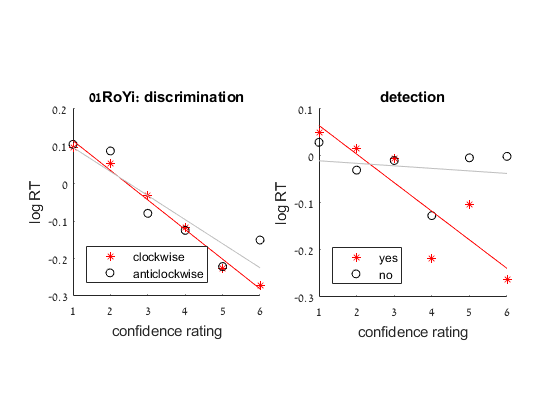

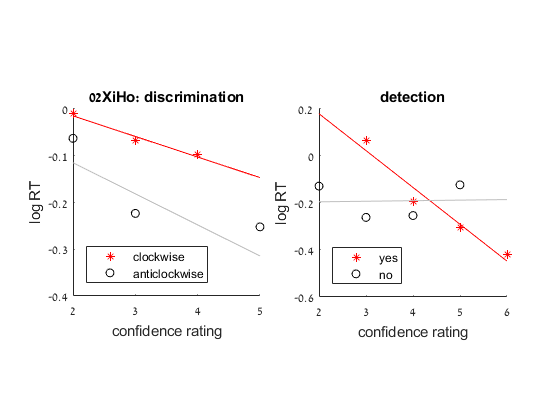

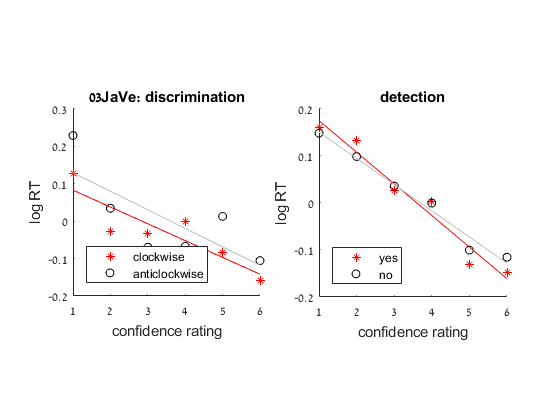

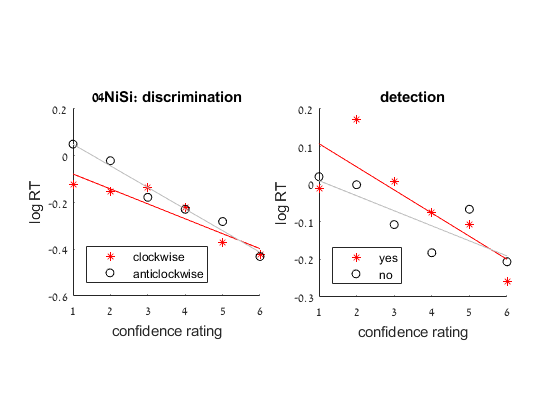

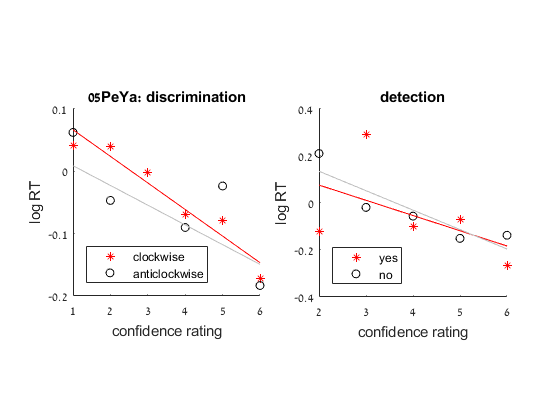

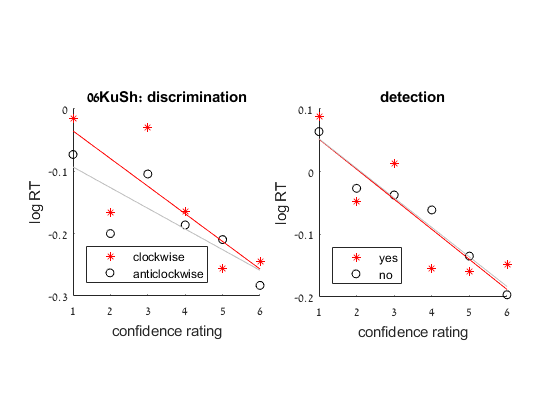

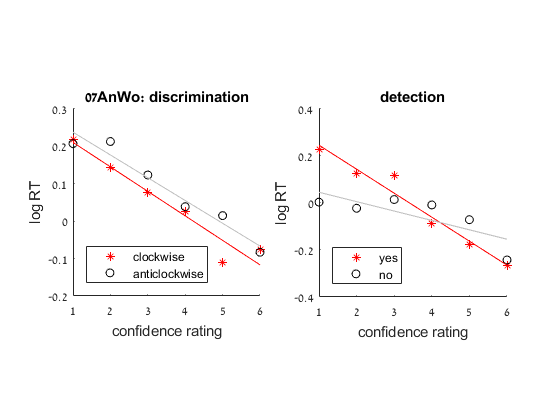

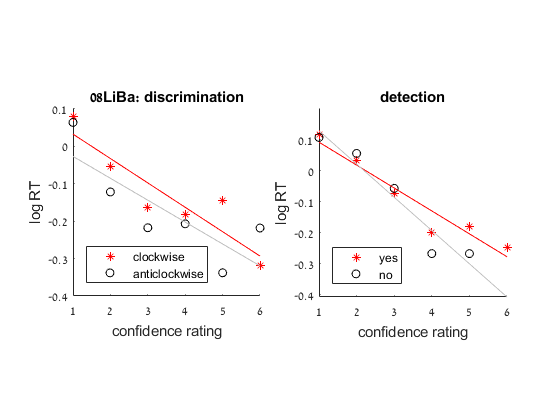

meanYesRTGroup = [];
meanNoRTGroup = [];
meanDownRTGroup = [];
meanUpRTGroup = [];

for s=1:length(subjects)

    subject = data_struct(subjects{s});
    
    yesConf = subject.DetConf(subject.DetResp==1);
    yesRT = log(subject.DetRT(subject.DetResp==1));
    
    noConf = subject.DetConf(subject.DetResp==0);
    noRT = log(subject.DetRT(subject.DetResp==0));
    
    upConf = subject.DisConf(subject.DisResp==1);
    upRT = log(subject.DisRT(subject.DisResp==1));
     
    downConf = subject.DisConf(subject.DisResp==0);
    downRT = log(subject.DisRT(subject.DisResp==0));
    
meanYesRT = [];
meanNoRT = [];
meanDownRT = [];
meanUpRT = [];

for rating = 1:6
    meanYesRT = [meanYesRT mean(yesRT(yesConf==rating))];
    meanNoRT = [meanNoRT mean(noRT(noConf==rating))];
    meanDownRT = [meanDownRT mean(downRT(downConf==rating))];
    meanUpRT = [meanUpRT mean(upRT(upConf==rating))];
end

meanYesRTGroup = [meanYesRTGroup;meanYesRT];
meanNoRTGroup = [meanNoRTGroup; meanNoRT];
meanUpRTGroup = [meanUpRTGroup; meanUpRT];
meanDownRTGroup = [meanDownRTGroup; meanDownRT];

figure;
subplot(1,2,1);
hold on;
pbaspect([1 1 1])

plot(1:6, meanUpRT, 'r*')
scatter(1:6, meanDownRT, 'ko')
lsline()
xlabel('confidence rating');
ylabel('log RT');
title([subjects{s}, ': discrimination']);
legend('clockwise', 'anticlockwise', 'Location', 'southwest')

subplot(1,2,2);
hold on;
pbaspect([1 1 1])

plot(1:6, meanYesRT, 'r*')
scatter(1:6, meanNoRT, 'ko')
lsline()
xlabel('confidence rating');
ylabel('log RT');
title('detection');
legend('yes', 'no', 'Location', 'southwest')

   disp(sprintf('%s ------------ YES RESPONSES ------------ %.2f',...
       subjects{s}, corr(yesConf,yesRT)))
   
   disp(sprintf('%s ------------- NO RESPONSES ------------ %.2f',...
       subjects{s}, corr(noConf,noRT)))
   
   disp(sprintf('%s --------- UP/RIGHT RESPONSES ---------- %.2f',...
       subjects{s}, corr(upConf,upRT)))
   
  disp(sprintf('%s --------- DOWN/LEFT RESPONSES --------- %.2f',...
       subjects{s}, corr(downConf,downRT)))
  disp('----------------------------------------------------')
end

figure;
subplot(1,2,1);
hold on;
pbaspect([1 1 1])

plot(1:6, nanmean(meanUpRTGroup), 'r*')
plot(1:6, nanmean(meanDownRTGroup), 'ko')
errorbar(1:6, nanmean(meanUpRTGroup), nanstd(meanUpRTGroup), 'r*')
errorbar(1:6, nanmean(meanDownRTGroup), nanstd(meanDownRTGroup),'ko')
lsline()
xlabel('confidence rating');
ylabel('log RT');
title('discrimination');
legend('clockwise', 'anticlockwise', 'Location', 'southwest')

subplot(1,2,2);
hold on;
pbaspect([1 1 1])

plot(1:6, nanmean(meanYesRTGroup), 'r*')
plot(1:6, nanmean(meanNoRTGroup), 'ko')
errorbar(1:6, nanmean(meanYesRTGroup),nanstd(meanYesRTGroup),'r*')
errorbar(1:6, nanmean(meanNoRTGroup), nanstd(meanNoRTGroup),'ko')
lsline()
xlabel('confidence rating');
ylabel('log RT');
title('detection');
legend('yes', 'no', 'Location', 'southwest')